# Figure 2:  BTSP shapes recurrent activity in CA3 framework on a circular track

### Fig B: Generate weight matrix before learning and after learning.

**Simulation protocol**: simulate the weight matrix of $N$ ca3 neurons over $n$ distinct environment, which mimic the animal exploring new environments. we store the weight matrix at $n-1$ environment as $W^{Bef}$ (weight matrix before learning with proper sorting according to the environment, the environment is encoding by the sequence of neurons id) and $W^{Aft}$ (weight matrix after learning with proper sorting) is the weight matrix due the learning at environment $n$. 

PD: weight matrix to plot is generate in the section **Figure 2B** with proper parameters in script ***9_generate_network_weight.mlx***

Export figure setup:: 7-7

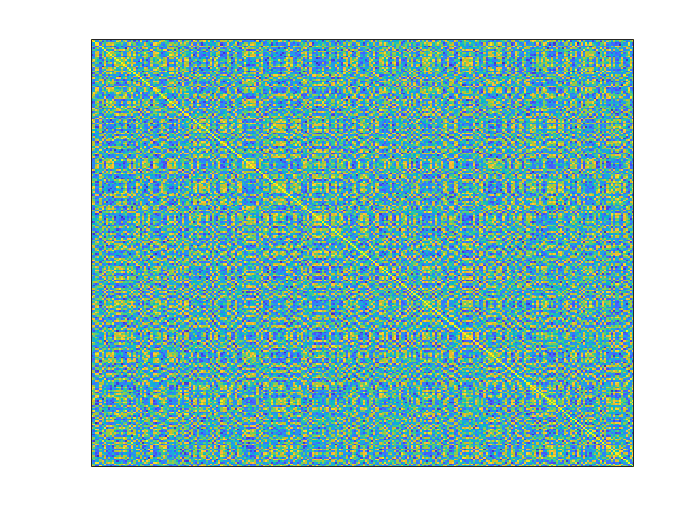

load Files\weight_matrix\Fig2\weight.mat
last_env = Env_track(:, end);
weight_before_learning = weight_before(last_env, last_env);
weight_after_learning = final_weight(last_env, last_env);

imagesc(weight_before_learning)
set(gca,'TickLength',[0 0])
xticklabels("")
yticklabels("")

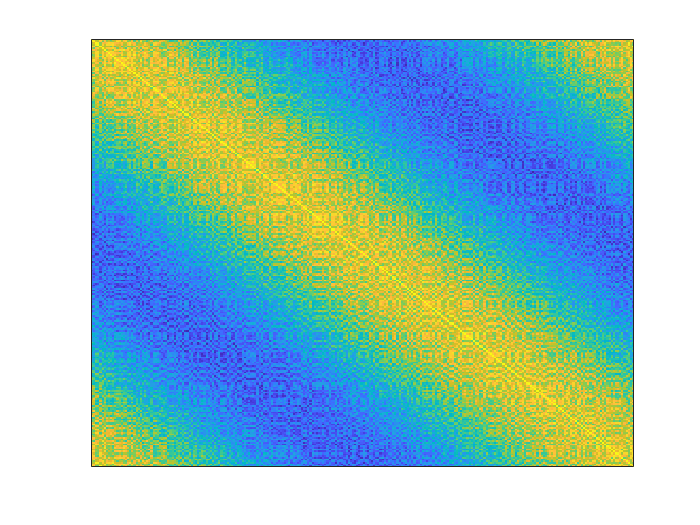

imagesc(weight_after_learning)
set(gca,'TickLength',[0 0])
xticklabels("")
yticklabels("")

### FigD: Plot for the overal mean and variance

For each iteration of 1D map, we already saved overall mean and overall variance of the weight matri, later are plotted to comprare the theoretical mean and variance.

Export figure setup: 9.3-7

inkscape size: 45-37.5

plot(1:10, weight_mean(1:10), ".k", "MarkerSize", 40)
theoretical_mean = P/(P+D);
yline(theoretical_mean, "-r", "LineWidth", 4.5)
ylim([0, theoretical_mean*1.25])
yticks([0, floor(theoretical_mean*1.25 *10)/10])
xlim([1, 10])
xticks([1,5, 10])
box off
legend(["Sim", "Theory"], "Location","best")
legend boxoff
fig_config(80)


plot(1:10, weight_var(1:10), ".k", "MarkerSize", 40)
theoretical_var = 2 * P^2 * D^2 / (P+D)^2 / (2 * (P*D + P + D) - 3/2 * (P+D)^2);
yline(theoretical_var, "r", "LineWidth", 4.5)
ylim([0, theoretical_var *1.25])

ylim([0, 0.1])
yticks([0, 0.1])
xlim([1, 10])
xticks([1,5, 10])
box off
fig_config(80)

### FigE: Representation of weight matrix in different environment

Once the weight matrix reach the steady state, we can plot the final weight w.r.t. previous environments by sorting them properly and align to the $\Delta\theta$.

After doing that, we compute the mean and the variance with same modification (at $\Delta\theta= 0$, the weight is always potentiated, so we smooth them to get nice plot) for different past environment denoted by $\eta= 0, 1, 2, 3$. $\eta= 0$ indicates the 0 past environment, which is corresponding to the last explored environment.

Export figure setup: 10.5-7    6-4?

inkscape size: 45-37.5

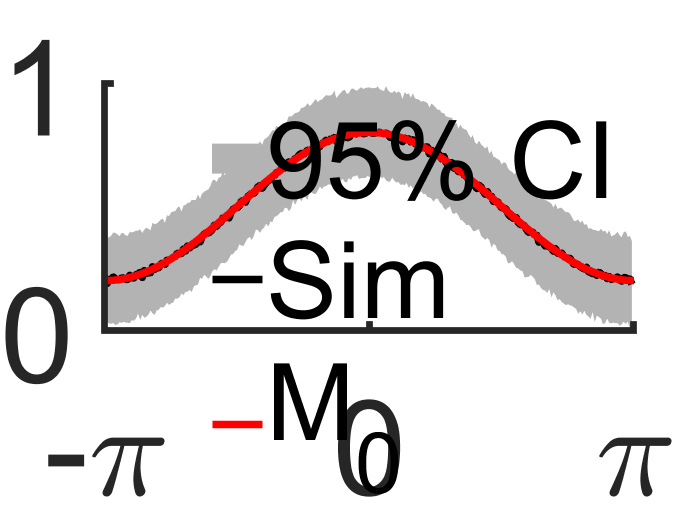

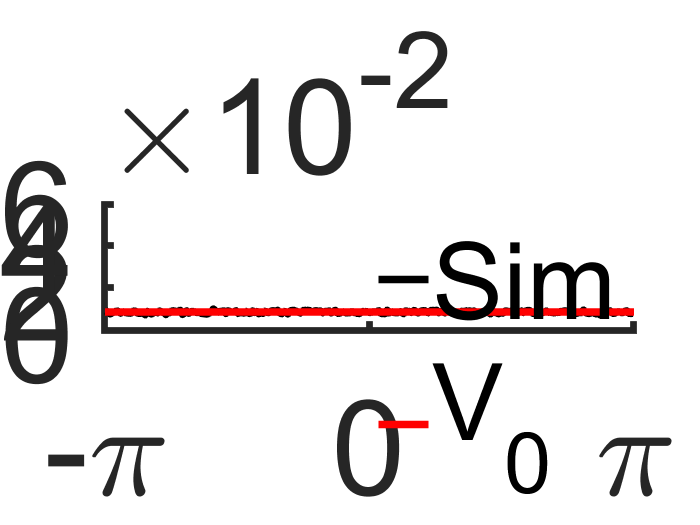

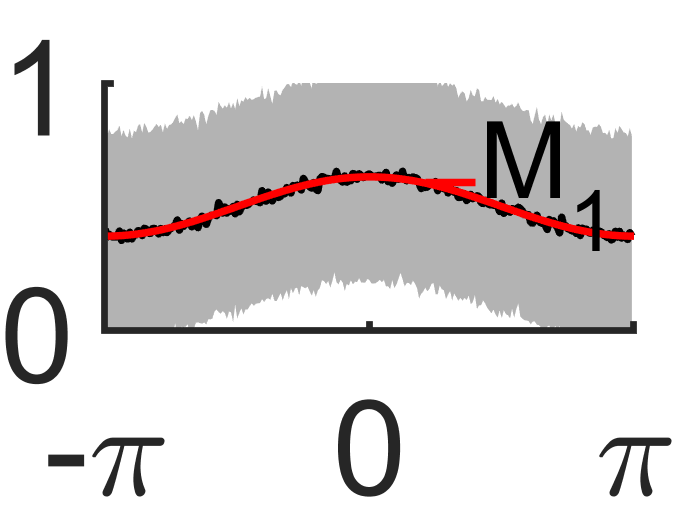

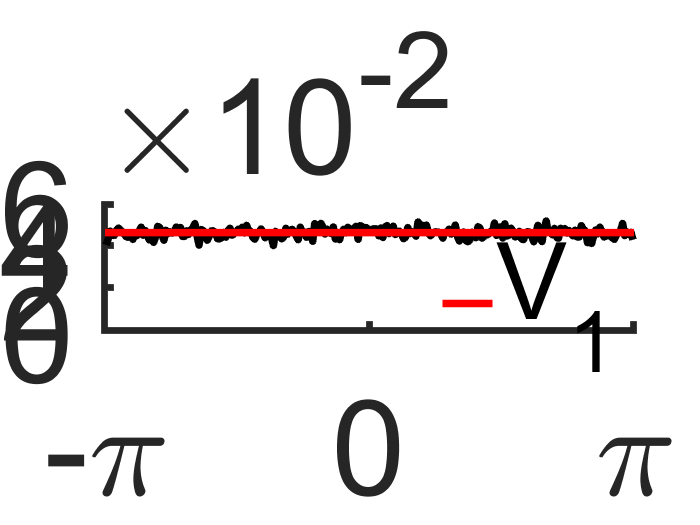

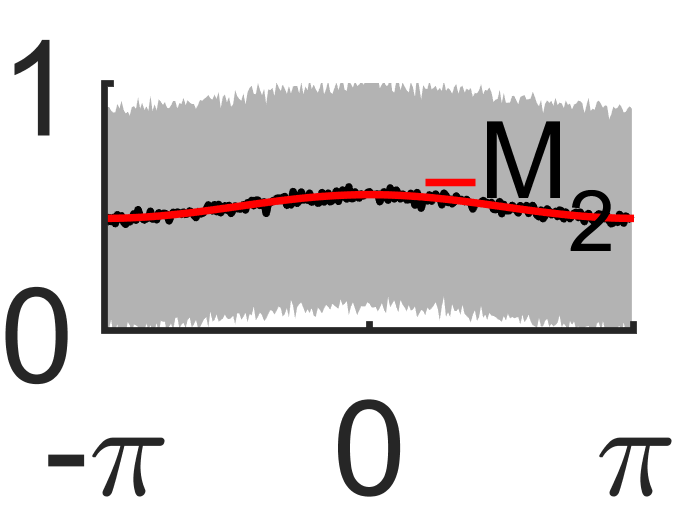

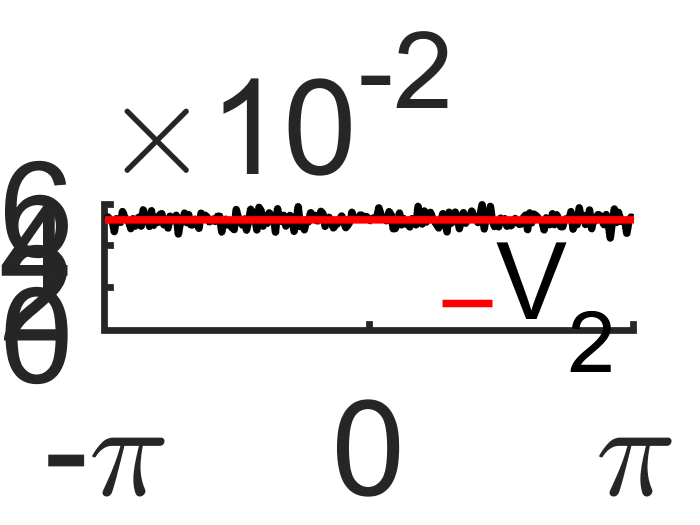

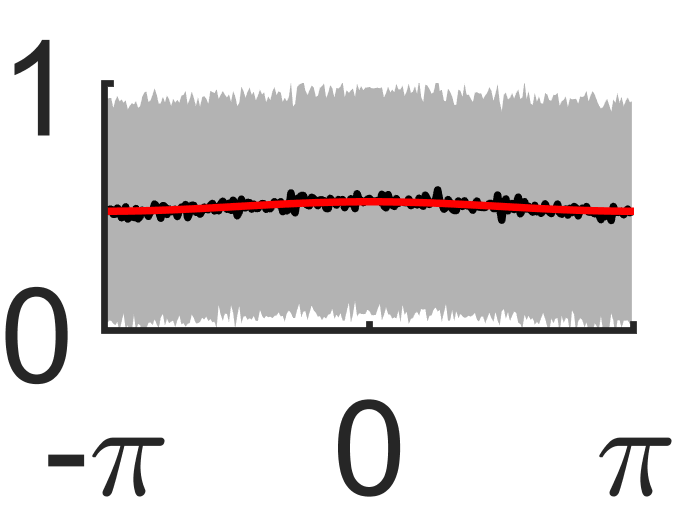

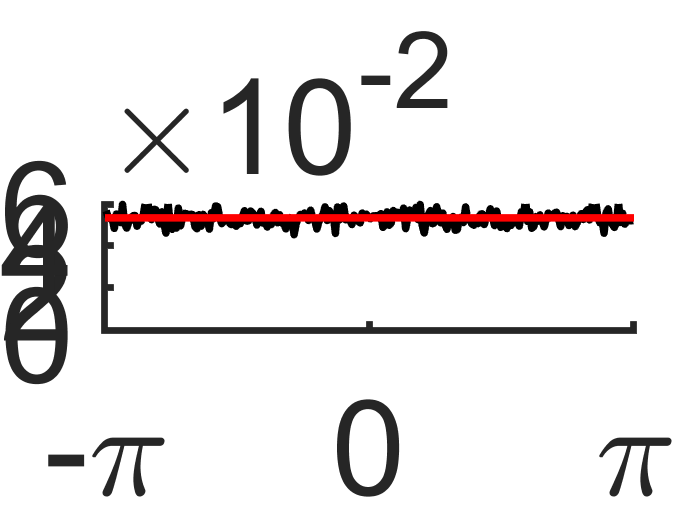

plot_mean_variance_curve(final_weight, Env_track, n_ca3_per_track, phase, ...
    P, D, M, s)

## Auxiliar function

function plot_mean_variance_curve(final_weight, Env_track, n_ca3_per_track, phase, ...
    P, D, M, s)
    is_stack = false;
    for k = [0, 1, 2, 3]
        rng(1997)
        [theo_mean, theo_var, theo_phase] = Compute_mean_variance(P, D, k, is_stack, M, s);
        [sort_weight_k, phase_modf] = Aligment(final_weight, Env_track, k, phase, n_ca3_per_track, M, s, is_stack);
        mean_weight = mean(sort_weight_k);
    
        % Since the phase for each cell to itself is always 0, then the
        % plasticty rule we defined before only remains the potentiation
        % part because the depression is always 0. 
        % To avoid the ugly representation of weight, we have either delete
        % the autolop point or smooth the autoconnection weight and also
        % the variance. 
        modified_weight = mean_weight;
        ind_logic = abs(phase_modf) < 0.3 & phase_modf ~= 0;
        attach_weight = mean_weight(ind_logic);
        modified_weight(abs(phase_modf) < 0.1) = normrnd(mean(attach_weight), std(attach_weight)/5, 1, ...
            length(modified_weight(abs(phase_modf) < 0.1)));

        noise = sort_weight_k - mean_weight;
        var_sim = var(noise);
        attach_var = var_sim(abs(phase_modf) < 0.3 & phase_modf ~= 0);
        var_sim(abs(phase) < 0.1) = normrnd(mean(attach_var), std(attach_var)/5, 1, length(var_sim(abs(phase) < 0.1)));
        
        upper_band = modified_weight + sqrt(var_sim) * 1.96;
        lower_band = modified_weight - sqrt(var_sim) * 1.96;
        figure
        h1 = fill([phase_modf', fliplr(phase_modf')], [upper_band, lower_band], [.7,.7,.7], ...
            'EdgeColor','none', 'FaceAlpha', 1);
        hold on
        plot(phase_modf, modified_weight, "k", "LineWidth", 4.5)
        plot(theo_phase, theo_mean, "r", "LineWidth", 4.5)
        hold off
        box off
        xlim([-pi, pi])
        xticks([-pi, 0, pi])
        xticklabels("")
        xticklabels(["-\pi", 0, "\pi"])
        ylim([0, 1])
        yticks([0, 1])

        if k == 0
            legend("95% CI", "Sim", "Theory", "FontSize", 80*0.7, "location", "northeast");
            legend boxoff
        end
        
        if k == 0
            legend("95% CI", "Sim", "M_0", "FontSize", 80*0.7, "location", "northeast");
            legend boxoff
        elseif k == 1
            hold on
            qw{1} = plot(nan, "r-", "LineWidth", 4.5);
            legend([qw{:}], {'M_1'}, "FontSize", 80*0.7, "location", "northeast")
            legend boxoff
            hold off
        elseif k == 2
            hold on
            qw{1} = plot(nan, "r-", "LineWidth", 4.5);
            legend([qw{:}], {'M_2'}, "FontSize", 80*0.7, "location", "northeast")
            legend boxoff
            hold off
        end
        
        
        fig_config(80)
        
        figure
        plot(phase, var_sim, "k", "LineWidth", 4.5)
        hold on
        plot(theo_phase, theo_var, "r", "LineWidth", 4.5)
        hold off
        box off
        xlim([-pi, pi])
        xticks([-pi, 0, pi])
        xticklabels(["-\pi", 0, "\pi"])
        
        aux = mean(var_sim);
        ylim([0, 0.06])
        yticks([0, 0.02, 0.04, 0.06])
        ax=gca; ax.YAxis.Exponent = -2;
        if k == 0
            legend(["Sim", "Theory"], "Location","northeast")
            legend boxoff
        end
        
        if k == 0
            legend(["Sim", "V_0"], "Location","northeast")
            legend boxoff
        elseif k == 1
            hold on
            qw{1} = plot(nan, "r-", "LineWidth", 4.5);
            legend([qw{:}], {'V_1'}, "location", "southeast")
            legend boxoff
            hold off
        elseif k == 2
            hold on
            qw{1} = plot(nan, "r-", "LineWidth", 4.5);
            legend([qw{:}], {'V_2'}, "location", "southeast")
            legend boxoff
            hold off
        end
        
        
        fig_config(80) 
    end
end